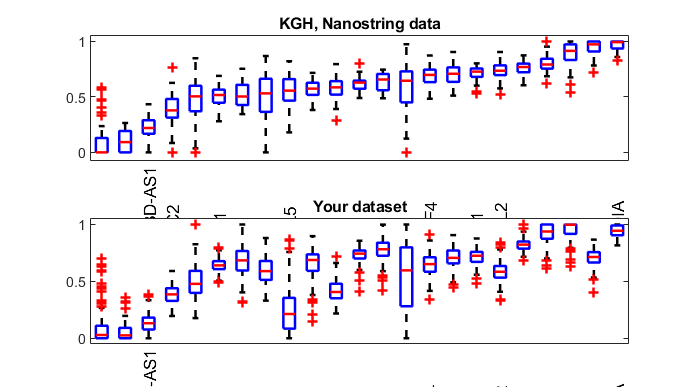

%___________________________________________________
%   Applying the TCF3 classifier
%___________________________________________________

%download all files, including the custom .m functions 
% Open MATLAB and place the files to your working directory or add the new
% files to path.

%load the datafile
load("classifier_structure.mat");

%% get the top selected genes from the data in the same order as were used
% in the classifier. The genenames are stored in the selected_genes variable
% in the classifier, he '-' in the gene names was replaced with '_', so
% need to replace it back
selected_genes = strrep(trainedClassifier_TCF3targets.ClassificationKNN.ExpandedPredictorNames, '_', '-');


%% load your data. Here we load the Lenz microarray data (), which is stored 
%in the 'celldataLenz_selected' variable. The samples are selected based on
%threatment (R-CHOP) and age >=18. 
mydata = celldataLenz_selected;

%% indicate the first row where the expression data starts
% e.g., if your data has a header, then data may start at row 2
rowWhereDataStarts = 2;
rowWithSampleNames = 1;
% indicate the first columns there the expression data starts
% e.g. if you have gene names and gene IDs as first 2 columns, then the
% data may start at column 3
colWhereDataStarts = 3;
columnWithGeneNames = 2; %column # with the gene names

%%extract the selected genes in the order they were used in the classifier -
%indicated by the 'stable' parameter
[~, ~, indB] = intersect(selected_genes, mydata(rowWhereDataStarts:end, columnWithGeneNames), 'stable');
notfound = setdiff(selected_genes, mydata(rowWhereDataStarts:end, columnWithGeneNames));
%check that notfound is empty - if it is not, check which genes were not
%found in your dataset. Alternatively look for synonims.

%CRITICAL: don't proceed any further unless you found all the matching
%genes

%% preprocess your data the same way as the training set
%the data must be log2 transformed and minmax standardized across the 
mydata_selected = mydata([1:rowWhereDataStarts-1; indB+rowWhereDataStarts-1], :);
mydata_numeric = cell2mat(mydata_selected(rowWhereDataStarts:end, colWhereDataStarts:end));
mydata_numeric = log2(replaceZeros(mydata_numeric, 'lowval'));
mydata_numeric = minmax_standardize(mydata_numeric, 2);

%visulize your data and compare the distributions for the selected
%genes accross samples. The better the match to our Nanostring data, the
%more optimal the classification will be. 
f = figure;
pos = get(f, 'Position');
set(f, 'Position', [pos(1), pos(2)-356, 860 480]);

KGH_numeric = cell2mat(celldata_KGH_selected(2:end, 2:end));
KGH_numeric = log2(replaceZeros(KGH_numeric, 'lowval'));
KGH_numeric = minmax_standardize(KGH_numeric, 2);
fsubs(1) = subplot(2, 1, 1);
sample_labels = celldata_KGH_selected(2:end, 1);
h=boxplot(fsubs(1), KGH_numeric', 'labels', sample_labels, 'labelorientation', 'inline');
set(h,{'linew'},{1.5});
title(fsubs(1), 'KGH, Nanostring data');

fsubs(2) = subplot(2, 1, 2);
sample_labels = mydata(rowWhereDataStarts:end, columnWithGeneNames);
h = boxplot(fsubs(2), mydata_numeric', 'labels', sample_labels, 'labelorientation', 'inline');
set(h,{'linew'},{1.5}); 
title(fsubs(2), 'Your dataset');

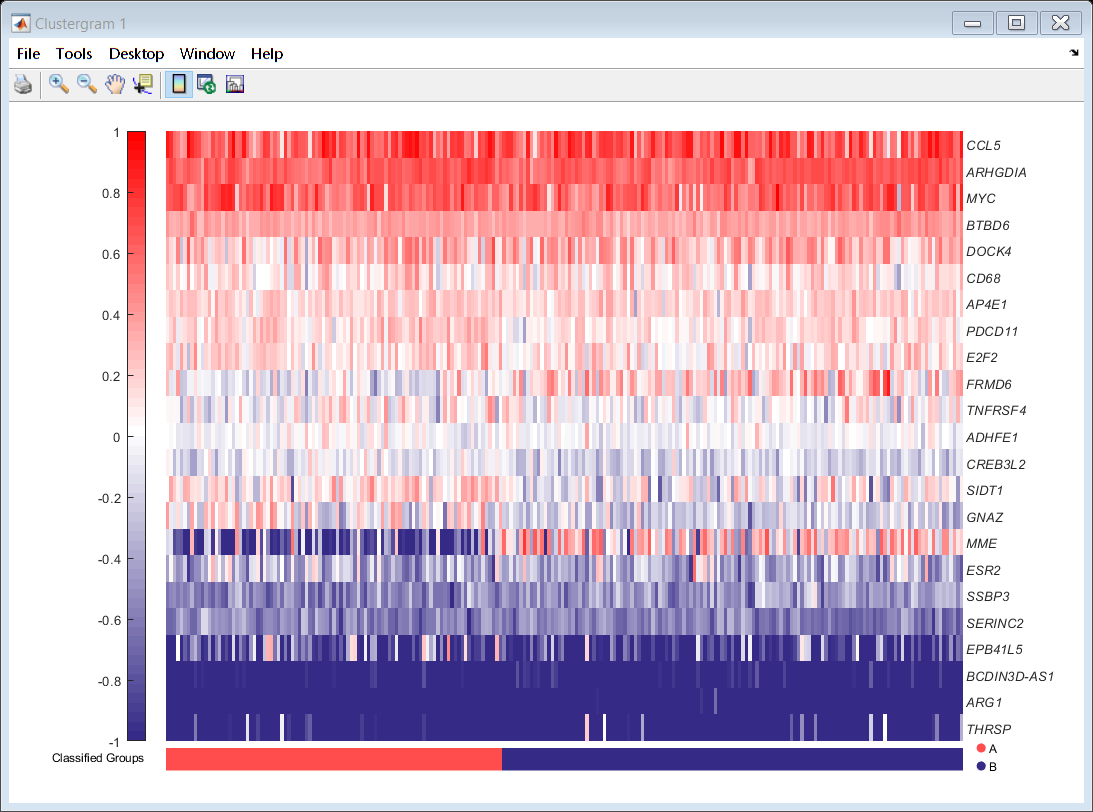


%Note, in this example we used a microarray data. Therefore, for some of
%the genes the range of expression is not matching between the two sets
%(e.g. 'EPB41L5'). In this case, the classification is possible, but not optimal

%%run classifier to classify the samples into cluster A or B, the results is
%1 = group A, 0 = group B
subtypeClass = trainedClassifier_TCF3targets.predictFcn(mydata_numeric); 

%%plot heatmap with the classified subtypes as a colour label
mydata_numeric = cell2mat(mydata_selected(rowWhereDataStarts:end, colWhereDataStarts:end));
mydata_numeric = log2(replaceZeros(mydata_numeric, 'lowval'));
mydata_numeric = mydata_numeric-median(median(mydata_numeric, 2));

%sort by the classification
[subtypeClass_sorted, indA] = sort(subtypeClass,'descend');
mydata_numeric = mydata_numeric(:, indA);
sample_labels = mydata(rowWithSampleNames, indA+colWhereDataStarts-1);
gene_labels = mydata(rowWhereDataStarts:end, columnWithGeneNames);

c = clustergram(mydata_numeric, 'RowLabels',gene_labels,...
    'ColumnLabels',sample_labels, 'RowPDist', 'euclidean',...
    'ColumnPDist', 'Spearman', 'Colormap', 'myColourMap_RedBlue',...
    'DisplayRange', 1,'Cluster', 1, 'ShowDendrogram', 'off');

red = [1, .3, .3];
blue = [.21, .17, .53];

% show classification results under the clustergram
clinical_labels = struct();
groups = cell(size(subtypeClass_sorted));
groups(1:end) = {'B'};
groups(subtypeClass_sorted==1) = {'A'};
clinical_labels.label1.labels = groups;
clinical_labels.label1.colours = [red; blue];
clinical_labels.label1.ordered_lbls = {'A', 'B'};
clinical_labels.label1.description = {'Classified Groups'};

figurePos = [20 150 860 560];
modifyClustergram(c, clinical_labels, 'ischangepossize', true, ...
    'newpos', figurePos, 'columnLabels', sample_labels, 'textfont', 8, ...
    'img_textfont', 7, 'outer_padding', .04, 'inner_padding', .01, ...
    'italicizeRowLabels', true);



clearvars indA indB KGH_numeric clinical_labels sample_labels gene_labels...
    c red blue notfound selected_genes rowWhereDataStarts rowWithSampleNames ...
    columnWithGeneNames colWhereDataStarts f figurePos fsubs groups h mydata ...
    mydata_numeric pos